% a) f(x) = x^a*ln(x)
clc
clear
x = linspace(0,1);
for n = 2:2:10
    f = @(x) (x.^n).*log(x);
    y = f(x);
    plot(x,y,'LineWidth',1.5);
    hold on;
    
    [x_m,y_m] = fminbnd(f,0,1);
    plot(x_m,y_m,'ok','MarkerFaceColor','r');
    str = sprintf('\t n = %d',n);
    text(x_m,y_m,str);
    hold on
end

% b) f(x) = x^a*e^-b*x
% здесь находим максимумы, я посчитал производные.
clc
clear
x = linspace(0,10);
for a = 1:1:3
    for b= 1:1:3
        f2 = @(x) (x.^a).*exp(-b*x);
        f2minus = @(x) -f2(x);
        y = f2(x);
        plot(x,y,'LineWidth',1.5);
        hold on;
        
        [x_n,y_n] = fminbnd(f2minus,0,10);
        x_m = x_n;
        y_m = -y_n;
        plot(x_m,y_m,'ok','MarkerFaceColor','r');
        str = sprintf('\t (a,b)=(%d,%d)',a,b);
        text(x_m,y_m,str);
        hold on
    end
end

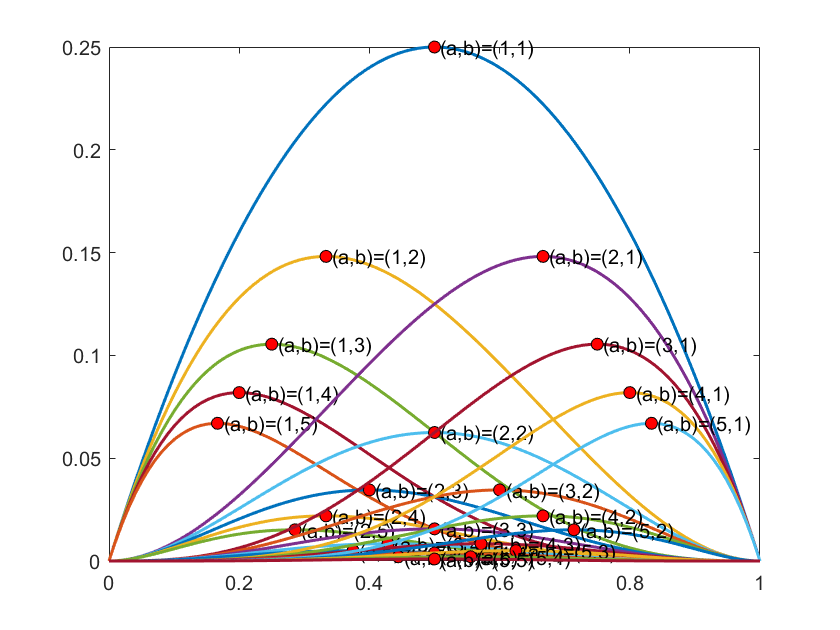

% c) f(x) = x^a(1-x)^b
% здесь тоже находим максимумы
clc
clear
x = linspace(0,1);
for a = 1:1:5
    for b= 1:1:5
        f2 = @(x) (x.^a).*(1-x).^b;
        f2minus = @(x) -f2(x);
        y = f2(x);
        plot(x,y,'LineWidth',1.5);
        hold on;
        
        [x_n,y_n] = fminbnd(f2minus,0,1);
        x_m = x_n;
        y_m = -y_n;
        plot(x_m,y_m,'ok','MarkerFaceColor','r');
        str = sprintf('\t (a,b)=(%d,%d)',a,b);
        text(x_m,y_m,str);
        hold on
    end
end